clear;close all;clc;

# **创建ROS环境**

rosshutdown;

Shutting down global node /matlab_global_node_14121 with NodeURI http://192.168.153.1:13366/


rosinit('192.168.153.130');

Initializing global node /matlab_global_node_07876 with NodeURI http://192.168.153.1:1071/


# **路径规划**

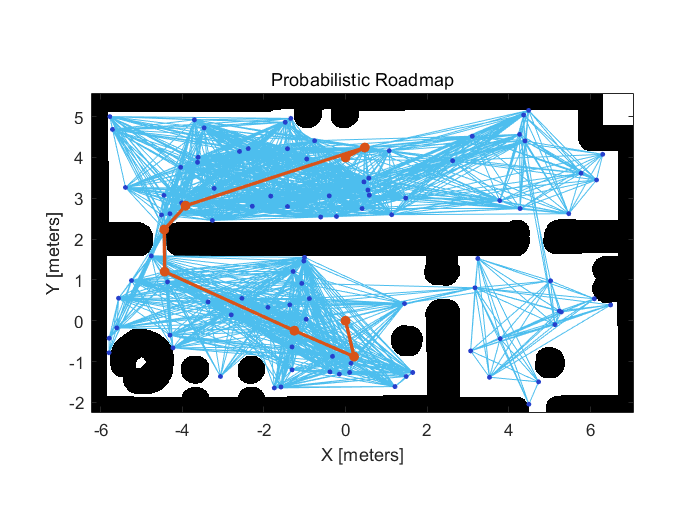

load("officemap.mat");

robotRadius=0.25;
mapInflated=copy(map);
inflate(mapInflated,(robotRadius+0.05)); %膨胀障碍物，得到机器人的位形空间

prm=mobileRobotPRM(mapInflated);%用PRM做路径规划
prm.NumNodes=100;
prm.ConnectionDistance=5;
%plannerRRT

startLocation = [0 0];  %设置起点
endLocation = [0 4];    %设置终点

path=findpath(prm, startLocation, endLocation); %找出可行路径
figure(1);
show(prm); %作图显示路径规划结果


robotCurrentLocation = [0.02 -0.05];    %定义机器人的初始位置
robotGoal = path(end,:);                %定义机器人的目标位置

initialOrientation = 0.01;              %定义机器人的初始朝向

robotCurrentPose = [robotCurrentLocation initialOrientation];   %定义机器人的当前位姿

# **无需创建机器人**

% robot = ExampleHelperDifferentialDriveRobot(robotCurrentPose);

# **创建控制器（纯追踪算法）**

controller = controllerPurePursuit;      % 创建算法
controller.Waypoints = path;             % 设置参数
controller.DesiredLinearVelocity = 0.3; 
controller.MaxAngularVelocity = 3;
controller.LookaheadDistance = 0.5;

goalRadius=0.05;
distanceToGoal=norm(robotCurrentLocation - robotGoal);

# ** 定义 Publisher 和 Subscriber**

velcomd=rospublisher('/mobile_base/commands/velocity');
%velcomd=rospublisher('/cmd_vel');
vel=rosmessage(velcomd);
odomsub=rossubscriber('/odom');

# **运动控制**

while( distanceToGoal > goalRadius )

[v1,omega1] = step(controller, robotCurrentPose);          % 根据当前Pose，计算速度和转角
vel.Linear.X=v1;
vel.Angular.Z=omega1;

send(velcomd,vel);                                         % 驱动机器人

odom=receive(odomsub,1);                                   % 收集位姿信息
robotCurrentPose=MyreadPose(odom);

robotCurrentLocation = robotCurrentPose(1:2);              % 获取驱动后Pose 
distanceToGoal = norm(robotCurrentLocation - robotGoal);   % 计算偏差

waitfor(rateControl(20));                                  % 延迟等待
end

在当前文件夹或 MATLAB 路径中未找到 'MyreadPose'，但它位于:
 F:\QQ接收的文件\k4-大四上\05-智能系统实践\课程资料\教学程序

更改 MATLAB 当前文件夹 或 将其文件夹添加到 MATLAB 路径。